# Instituto Tecnológico de Aeronaútica

### Aluno: Eduardo Bezerra Robalinho Dantas da Gama;

### Professor: Dr. Francisco Alex Correia Monteiro

O método de monte carlo consiste em:

Número de números gerados

m=1600;

Tamanho do domínio trabalhado:

r=rand(m,3);
x=zeros(m,3);

Função desigualdade

count=0;
for i=1:m
    %Tamanho do intervalo onde estou colocando os pontos unif distrib
    u=2*r(i,1)-1;
    v=(2*r(i,2)-1)*sqrt(1-u^2);
    w=(2*r(i,3)-1)*sqrt(1-u^2-v^2);
    if u^2+v^2+w^2<=1 & u>0 & v>0 & w>0
        x(i,1)=u;
        x(i,2)=v;
        x(i,3)=w;
        count=count+1;
      end
end

Vetor para receber o resultado das operações:

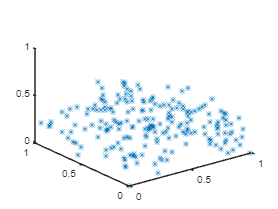

plot3(x(:,1),x(:,2),x(:,3),'*')